% Load Raw Signals (Optional visualization)
healthy_flow = readtable('healthy_signals.csv');
faulty_flow = readtable('faulty_signals.csv');

% Load the 14-dimensional feature set
df = readtable('pump_features.csv');

% Standardize and reduce to 2D via PCA
X = df{:, 1:14};
X_scaled = zscore(X);
[~, score, ~, ~, explained] = pca(X_scaled);
X_2d = score(:, 1:2);

K = 3; % Number of fault components
options = statset('MaxIter', 1000, 'TolFun', 1e-6);
gmm = fitgmdist(X_2d, K, 'RegularizationValue', 0.01, 'Options', options);

% Hard clustering labels
idx = cluster(gmm, X_2d);

% Responsibilities (Soft Clustering)
P = posterior(gmm, X_2d);

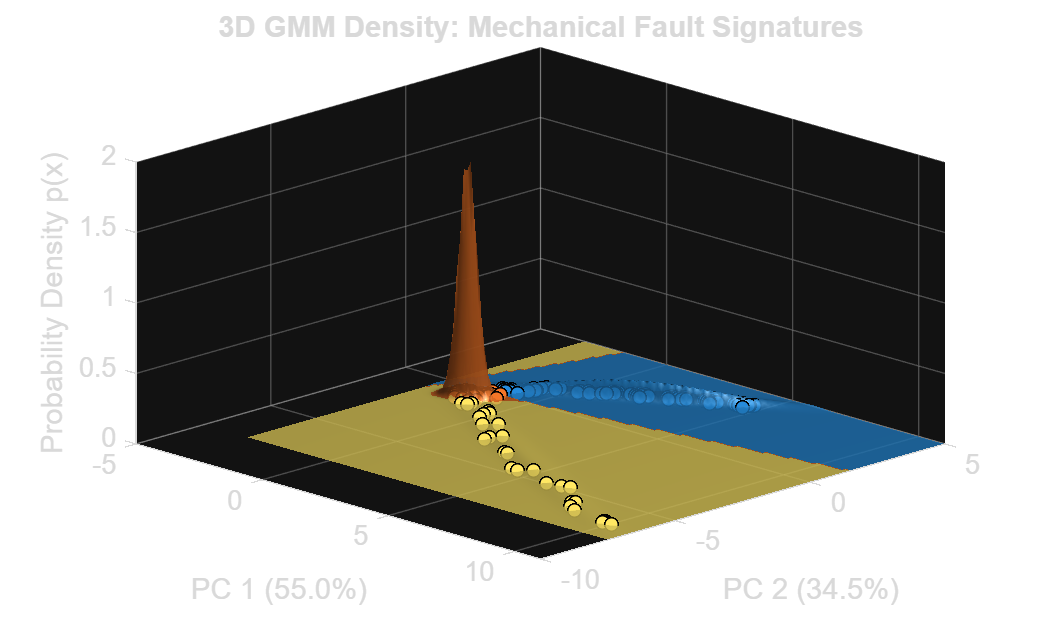

% Generate grid for PDF evaluation
x_range = linspace(min(X_2d(:,1))-1, max(X_2d(:,1))+1, 100);
y_range = linspace(min(X_2d(:,2))-1, max(X_2d(:,2))+1, 100);
[X_grid, Y_grid] = meshgrid(x_range, y_range);

% Evaluate p(x)
Z = pdf(gmm, [X_grid(:), Y_grid(:)]);
Z = reshape(Z, size(X_grid));

% Get dominant component per grid point for class-based coloring
[~, grid_labels] = max(posterior(gmm, [X_grid(:), Y_grid(:)]), [], 2);
grid_labels = reshape(grid_labels, size(X_grid));

% Plotting
figure('Color', 'w');
surf(X_grid, Y_grid, Z, grid_labels, 'EdgeColor', 'k', 'EdgeAlpha', 0.1, 'FaceAlpha', 0.8);
hold on;

% Project original data points to the Z=0 plane
scatter3(X_2d(:,1), X_2d(:,2), zeros(size(X_2d,1),1), 25, idx, 'filled', 'MarkerEdgeColor', 'k');

% Aesthetics and Depth
colormap(lines(K));
view(45, 30);
grid on;
title('3D GMM Density: Mechanical Fault Signatures');
xlabel(sprintf('PC 1 (%.1f%%)', explained(1)));
ylabel(sprintf('PC 2 (%.1f%%)', explained(2)));
zlabel('Probability Density p(x)');
shading interp; % Smooths the color transitions between classes
camlight; lighting gouraud; % Adds depth via lighting